# Loading the Fashion MNIST dataset

% Load training data (images and labels)
[train_images, train_labels] = load_data('D:\Messina\Data analysis\Second year\Third semester\DEVICES FOR ARTIFICIAL INTELLIGENCE\My CNN\train-images-idx3-ubyte', ...
    'D:\Messina\Data analysis\Second year\Third semester\DEVICES FOR ARTIFICIAL INTELLIGENCE\My CNN\train-labels-idx1-ubyte');

num_images: 60000
num_rows: 28
num_cols: 28



% Load test data (images and labels)
[test_images, test_labels] = load_data('D:\Messina\Data analysis\Second year\Third semester\DEVICES FOR ARTIFICIAL INTELLIGENCE\My CNN\t10k-images-idx3-ubyte', ...
    'D:\Messina\Data analysis\Second year\Third semester\DEVICES FOR ARTIFICIAL INTELLIGENCE\My CNN\t10k-labels-idx1-ubyte');

num_images: 10000
num_rows: 28
num_cols: 28



% Check the sizes of the data
disp("Training Images Size: " + size(train_images));

    "Training Images Size: 28"    "Training Images Size: 28"    "Training Images Size: 60000"



disp("Training Labels Size: " + size(train_labels));

    "Training Labels Size: 60000"    "Training Labels Size: 1"



disp("Test Images Size: " + size(test_images));

    "Test Images Size: 28"    "Test Images Size: 28"    "Test Images Size: 10000"



disp("Test Labels Size: " + size(test_labels));

    "Test Labels Size: 10000"    "Test Labels Size: 1"



## Preprocessing step(Normalization)

% Normalize the images (scale pixel values to [0, 1])
train_images = double(train_images) / 255;
test_images = double(test_images) / 255;

% Convert labels to categorical type (No need for one-hot encoding)
train_labels_cat = categorical(train_labels);
test_labels_cat = categorical(test_labels);


% Check the size of the data
disp(['Training data size: ', num2str(size(train_images))]);

Training data size: 28     28  60000


disp(['Test data size: ', num2str(size(test_images))]);

Test data size: 28     28  10000


disp(['Training labels size: ', num2str(size(train_labels_onehot))]);

Training labels size: 10  60000


disp(['Test labels size: ', num2str(size(test_labels_onehot))]);

Test labels size: 10  10000


## The neural network architecture

layers = [
    imageInputLayer([28 28 1], 'Name', 'input', 'Normalization', 'none') 
    
    convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'conv1')
    batchNormalizationLayer('Name', 'bn1') % Batch normalization layer
    reluLayer('Name', 'relu1')
    
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool1')
    
    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'conv2')
    batchNormalizationLayer('Name', 'bn2') % Batch normalization layer
    reluLayer('Name', 'relu2')
    
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool2')
    
    fullyConnectedLayer(128, 'Name', 'fc1')
    reluLayer('Name', 'relu_fc1')
    
    fullyConnectedLayer(10, 'Name', 'fc2')
    softmaxLayer('Name', 'softmax')
    
    classificationLayer('Name', 'output')
];

% Display the CNN architecture
disp(layers);

  14×1 Layer array with layers:

     1   'input'      Image Input             28×28×1 images
     2   'conv1'      2-D Convolution         32 3×3 convolutions with stride [1  1] and padding 'same'
     3   'bn1'        Batch Normalization     Batch normalization
     4   'relu1'      ReLU                    ReLU
     5   'maxpool1'   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'      2-D Convolution         64 3×3 convolutions with stride [1  1] and padding 'same'
     7   'bn2'        Batch Normalization     Batch normalization
     8   'relu2'      ReLU                    ReLU
     9   'maxpool2'   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'fc1'        Fully Connected         128 fully connected layer
    11   'relu_fc1'   ReLU                    ReLU
    12   'fc2'        Fully Connected         10 

## Training step

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:21 |        7.81% |        7.22% |       3.0705 |       3.1909 |      1.0000e-04 |
|       1 |          50 |       00:00:53 |       48.44% |       56.95% |       1.5462 |       1.4218 |      1.0000e-04 |
|       1 |         100 |       00:01:25 |       70.31% |       68.43% |       1.1332 |       1.0395 |      1.0000e-04 |
|       1 |         150 |       00:01:58 |       78.12% |       72.45% |       0.7788 |       0.8859 |      1.0000e-04 |
|       

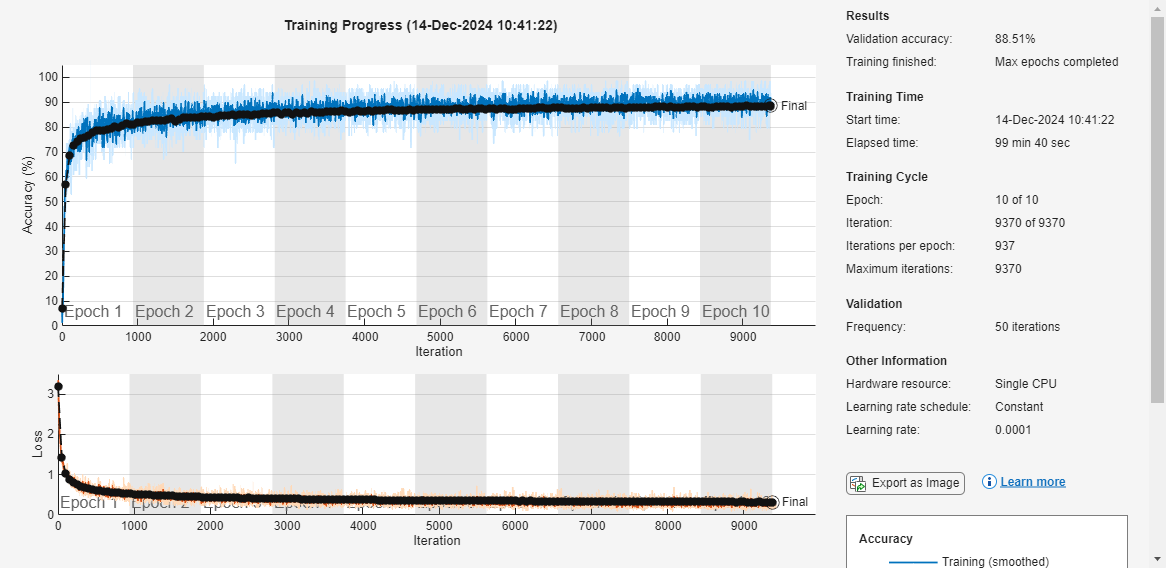

% Prepare training data
XTrain = reshape(train_images, 28, 28, 1, []); % Reshape to [28x28x1xNumImages]
YTrain = train_labels_cat;  % Labels are already categorical


% Prepare testing data
XTest = reshape(test_images, 28, 28, 1, []);  % Reshape to [28x28x1xNumImages]
YTest = categorical(test_labels);            % Convert labels to categorical
options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.0001, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 64, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', true, ...
    'ValidationData', {XTest, YTest}, ...
    'Plots', 'training-progress');
% Train the network
net = trainNetwork(XTrain, YTrain, layers, options);


% Save the trained network
save('trainedFashionCNN.mat', 'net');

% Evaluate the trained network on the test data
YPred = classify(net, XTest);

% Calculate the accuracy on the test set
accuracy = sum(YPred == YTest) / numel(YTest);
disp(['Test Accuracy: ', num2str(accuracy)]);

Test Accuracy: 0.8851


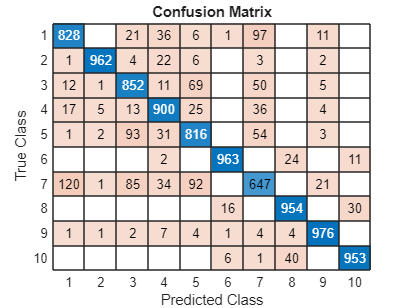


% Generate confusion matrix
cm = confusionmat(YTest, YPred);
confusionchart(cm, 'Title', 'Confusion Matrix');

% Read a new image
img = imread('D:\Messina\Data analysis\Second year\Third semester\DEVICES FOR ARTIFICIAL INTELLIGENCE\My CNN\test3.jpg');  % Replace with the path to your image


% Resize it to 28x28 pixels
img_resized = imresize(img, [28, 28]);

% Convert to grayscale if the image is RGB (3 channels)
if size(img_resized, 3) == 3
    img_resized = rgb2gray(img_resized);
end

% Normalize the image (scale pixel values to [0, 1])
img_norm = double(img_resized) / 255;

% Reshape the image to match the input format [28x28x1]
img_input = reshape(img_norm, [28, 28, 1]);

% Classify the image using the trained CNN
predicted_label = classify(net, img_input);

% Define class names for Fashion MNIST
class_names = {
    'T-shirt/top', 'Trouser', 'Pullover', 'Dress', 'Coat', ...
    'Sandal', 'Shirt', 'Sneaker', 'Bag', 'boot'
};

% Get the actual class name from the predicted label
predicted_class_name = class_names{double(predicted_label) + 1};  % Add 1 for MATLAB indexing

% Display the predicted label and the corresponding class name
disp(['Predicted Label: ', char(predicted_label)]);

Predicted Label: 8


disp(['Predicted Class Name: ', predicted_class_name]);

Predicted Class Name: boot


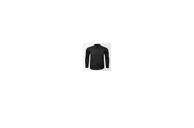


% Display the resized image
imshow(img_resized);